## Conexión con el Robot.

Se busca en las conexiones USB y se espera el comando.

Robot = ArduinoManager();

Initializing Arduino Manager...
Scanning ports: COM7
Probing COM7... SUCCESS! Arduino found.


## Inicialización.

Moviendo los servos a 90º

Robot.setServos(0, 0);
 

## Posiciones nuevas

Con los "sliders" puedes seleccionar las nuevas posiciones del robot.

P1 = 35

P1 = 35

P2 = 30

P2 = 30

## Enviar comando

Robot.setServos(P1, P2);
[x, y] = cinem_directa_analitica(P1, P2)

x = 12.6029

y = 14.0130

[xd, yd] = cinematica_DH(P1, P2)

xd = 12.6029

yd = 14.0130

## Actualización continua

Con los "sliders" puedes seleccionar las nuevas posiciones del robot.

P1 = 12;
P2 = -8;
Robot.setServos(P1, P2);
[x, y] = cinem_directa_analitica(P1, P2)

x = 19.2389

y = 2.8800

[xd, yd] = cinematica_DH(P1, P2)

xd = 19.2389

yd = 2.8800

## Cinemática directa y espacio de trabajo

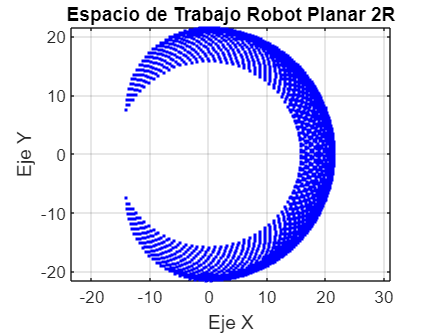

EspacioDeTrabajo(7.5, 14);

## Uso de la cinemática inversa

Introduce las coordenadas X, Y deseadas. 

Asegurate que pertenezcan al espacio de trabajo!

X = 25        

X = 25

Y = 0

Y = 0

[P1, P2] = ik_geometrica(X, Y)

P1 = -33.8078

P2 = 54.9097

Robot.setServos(P1, P2);
 

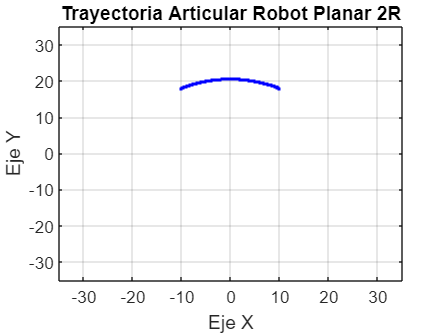

Unrecognized function or variable 'L1'.

Error in TrayectoriaArticular (line 38)
    plot([0, L1*cos(0.5)], [0, L1*sin(0.5)], 'r-o', 'LineWidth', 2)

qMatrix = TrayectoriaArticular(18, 10, 18, -10)

Robot.ejecutarTrayectoria(qMatrix, 2)

Unable to resolve the name 'Robot.ejecutarTrayectoria'.